# Trajectory Generation

## Load the map

map = load('trajectories/complexmap2.mat');

map = map.complexMap;
map2 = map;
map

map = 41×52 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0  

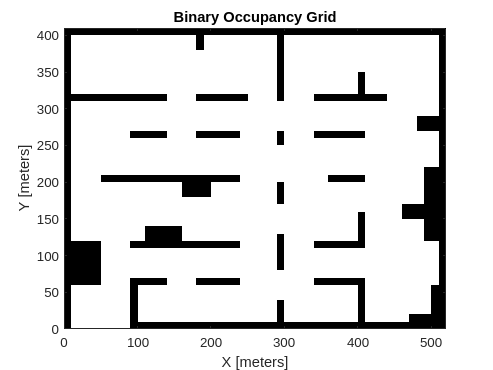

Resolution=.1; % meters
map2 = binaryOccupancyMap(map2,Resolution);
map2 = binaryOccupancyMap(map2);
uavRadius = 2;

Resolution=.1; % meters
map = binaryOccupancyMap(map,Resolution);
map = binaryOccupancyMap(map);


% inflate map
inflate(map2,uavRadius);
show(map)

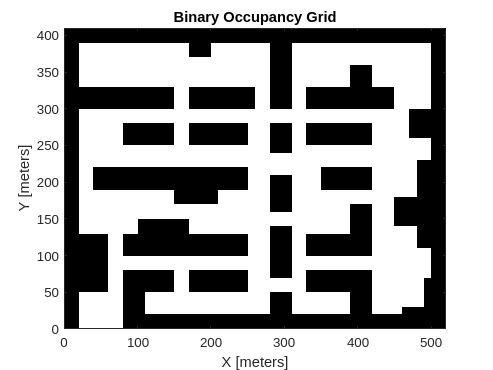

show(map2)

## Create waypoints

start = [50 25];

p1 = [140 90];
p2 = [125 180];
p3 = [250 40];
p4 = [340 155];
p5 = [315 225];
p6 = [190 360];
p7 = [75 290];
p8 = [140 380];
p9 = [290 290];
p10 = [40 140];
p11 = [320 160];
p12 = [440 50];
p13 = [200 230];
p14 = [435 210];
p15 = [260 275];
p16 = [295 60];
p17 = [370 370];
p18 = [390 240];
p19 = [110 240];
p20 = [260 140];
p21 = [100 350];
p22 = [220 360];
all_waypoints = [p1; p2; p3; p4; p5; p6; p7; p8; p9; p10; p11; p12; p13; p14; p15; p16; p17; p18; p19; p20; p21; p22];
waypoints = all_waypoints;
%waypoints = [p11; p18; p8]
%waypoints = [p19; p6; p9; p11; p20]
waypoints = [start; p1; p3; p16; p4; p18; p17; start]

waypoints =     50    25
   140    90
   250    40
   295    60
   340   155
   390   240
   370   370
    50    25


## Visualize map and waypoints

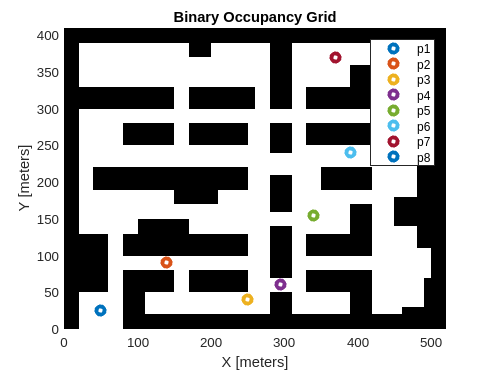

f1 = figure(1); clf;
hold on;
show(map2);
%plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints(:,1))
%for i = 1:length(trajectory.x_waypoints)
 %   plot(trajectory.x_waypoints(i), trajectory.y_waypoints(i), 'o', 'LineWidth', 3)
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3, 'DisplayName', sprintf("p%d", i)); 
end
hold off;
legend;


%waypoints = [p1; p2]
prm = mobileRobotPRM;
prm.Map = map2;

prm.NumNodes = 1000;
prm.ConnectionDistance = 50;

%path = findpath(prm, start, waypoints(1,:));
path = findpath(prm, waypoints(1,:), waypoints(2,:));
for i = 3:length(waypoints(:,1))
   p = findpath(prm, waypoints(i-1,:), waypoints(i,:));
   path = [path; p];
end

[~, iA] = uniquetol(path, 'byrows', true);
path = path(sort(iA), :);
path = [path; start];


## Calculate flight parameters

desiredVelocity = 3; % m/s
max_vel = 7;
max_accel = 2;
path_distance = calculatedistance(path) % total distance to be covered

path_distance = 1.3036e+03

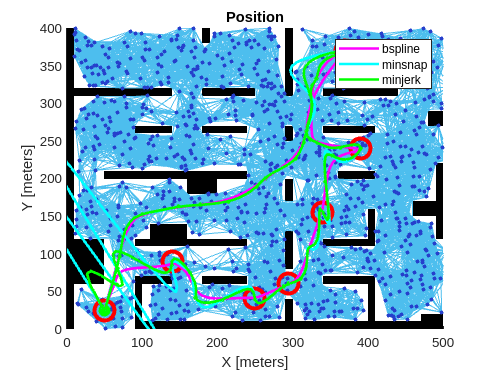

time_interval = calculatetime(path_distance,desiredVelocity); 

arrival_times = zeros(length(path),1);
for i=1:length(path)-1
    dist = calculatedistance(path(i:i+1,1:2));
    t = calculatetime(dist, desiredVelocity);
    arrival_times(i+1) = arrival_times(i) + t(2)*1.0;
end

% generate smooth time stamped trajectory
sampletimetraj=2; % 0.5 seconds by default
tSamples = 1:sampletimetraj:time_interval(2);
path_time = time_interval(2)/60;
numsamples = round(path_time*60/2);
%Compute minimum snap trajectories. The function outputs the trajectory positions (q), velocity (qd), acceleration (qdd), jerks (qddd), and snaps (qdddd) at the given number of samples.

[q1,qd1,qdd1,qddd1,qdddd1,pp1,timepoints,tsamples] = minsnappolytraj(path',arrival_times',numsamples);
[q2,qd2,qdd2,qddd,pp2,timepoints,tsamples] = minjerkpolytraj(path',arrival_times',numsamples);
%[q,qd,qdd,pp] = quinticpolytraj(path',arrival_times',tSamples);
[q,qd,qdd,pp] = bsplinepolytraj(path',time_interval,tSamples);

qd(3,:) = sqrt(qd(1,:).^2 + qd(2,:).^2);
qdd(3,:) = sqrt(qdd(1,:).^2 + qdd(2,:).^2);

x_ref_points = q(1,:)';
y_ref_points = q(2,:)';

vellim = [-max_vel max_vel; -max_vel max_vel]; 
accellim = [-max_accel max_accel; -max_accel max_accel];
%[q1,qd1,qdd1,t2] = contopptraj(pp,vellim,accellim,numsamples=numsamples);

x1_ref_points = q1(1,:)';
y1_ref_points = q1(2,:)';

qd1(3,:) = sqrt(qd1(1,:).^2 + qd1(2,:).^2);
qdd1(3,:) = sqrt(qdd1(1,:).^2 + qdd1(2,:).^2);


x2_ref_points = q2(1,:)';
y2_ref_points = q2(2,:)';

qd2(3,:) = sqrt(qd2(1,:).^2 + qd2(2,:).^2);
qdd2(3,:) = sqrt(qdd2(1,:).^2 + qdd2(2,:).^2);

f2 = figure(2); clf;
hold on;
prm.Map = map;
show(prm);
% plot(tInfo.Waypoints(:,1),tInfo.Waypoints(:,2),'k*')
h = zeros(1,7);
h(1) = plot(path(:,1), path(:,2), 'g.', 'MarkerSize', 10, 'DisplayName', 'path_points');
h(2) = plot(waypoints(:,1), waypoints(:,2), 'ro', 'markersize', 15, 'linewidth', 3);
%plot(path(:,1), path(:,2), 'r.', 'MarkerSize', 5)
% for i = 1:length(waypoints(:,1))
%    plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3); 
% end
% for i = 2:length(path-1)
%     plot([path(i-1,1) path(i, 1)], [path(i-1,2) path(i, 2)], 'b');
% end
h(3) = plot(start(1), start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
h(4) = plot(x_ref_points, y_ref_points, 'm-', 'LineWidth', 2, 'displayname', 'bspline');
h(5) = plot(x1_ref_points, y1_ref_points, 'c-', 'LineWidth', 2, 'displayname', 'minsnap');
h(6) = plot(x2_ref_points, y2_ref_points, 'g-', 'LineWidth', 2, 'displayname', 'minjerk');

% while ~isDone(trajectory)
%    [pos, ~, ~, ~, ~] = trajectory();
% 
%    plot(pos(1),pos(2),'bo')
% 
%    %pause(trajectory.SamplesPerFrame/trajectory.SampleRate)
%   %count = count + 1;
% end

hold off;
title("UAV Flight Path and Waypoints")


title('Position')
axis([0,500,0,400])
daspect([1 1 1])
legend(h(4:6));

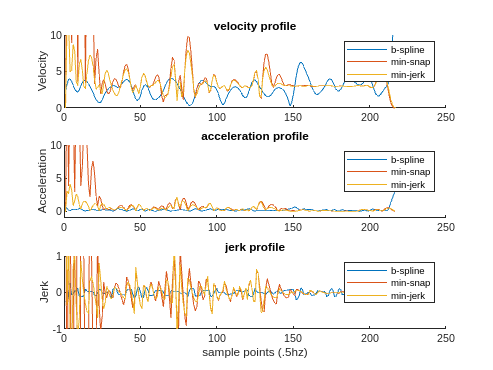


f3 = figure(3); clf;
%f3.Position = [0 0 900 900];
subplot(3,1,1);
title("velocity profile")
hold on;
plot(qd(3,:), 'displayname', 'b-spline');
plot(qd1(3,:), 'displayname', 'min-snap');
plot(qd2(3,:), 'displayname', 'min-jerk');
hold off;
ylabel('Velocity');
axis([0,250,0,10]);
legend;

subplot(3,1,2);
title("acceleration profile")
hold on;
plot(qdd(3,:), 'displayname', 'b-spline');
plot(qdd1(3,:), 'displayname', 'min-snap');
plot(qdd2(3,:), 'displayname', 'min-jerk');
hold off;
ylabel('Acceleration');
axis([0,250,-1,10]);
legend;

subplot(3,1,3);
title("jerk profile")
hold on;
plot(diff(qdd(3,:)), 'displayname', 'b-spline');
plot(diff(qdd1(3,:)), 'displayname', 'min-snap');
plot(diff(qdd2(3,:)), 'displayname', 'min-jerk');
hold off;
axis([0,250,-1,1])
ylabel('Jerk');
xlabel('sample points (.5hz)')
%axis([0,250,0,10]);
legend;